# Problem Set 4

## Problem 1

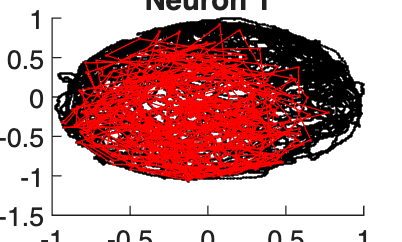

% Part A
figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike_idx = find(spikes);
plot(xN(spike_idx), yN(spike_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 1')

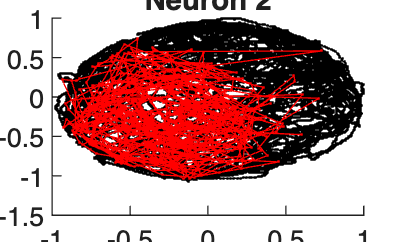


figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike2_idx = find(spikes2);
plot(xN(spike2_idx), yN(spike2_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 2')

The spatial firing properties of the two neurons

% Part B
[b,dev,stats] = glmfit([xN yN],spikes,'poisson');
% b = maximum likelihood estimate [b_0, b_1, b_2]
% dev = model deviance (dev = -2log(theta))
% stats.se = standard error
% stats.p = p-values
disp(stats.p)

   1.0e-26 *

         0
    0.8482
    0.0000



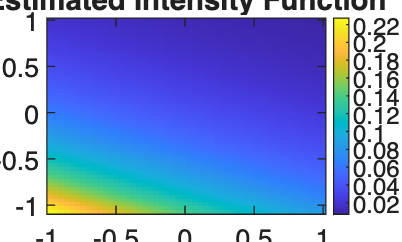

[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + b(2)*xgrid + b(3)*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Estimated Intensity Function');
xlabel('x'); ylabel('y');

The resulting parameters estimates are significant

% Part C
X = [xN yN xN.^2 yN.^2 xN.*yN];

[b, dev, stats] = glmfit(X, spikes, 'poisson');
disp(stats.p)
[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + ...
             b(2)*xgrid + ...
             b(3)*ygrid + ...
             b(4)*xgrid.^2 + ...
             b(5)*ygrid.^2 + ...
             b(6)*xgrid.*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Quadratic GLM Intensity');
xlabel('x'); ylabel('y');